# This script contains the development of the point 3.3) Estimation of the friction parameters.

simul.select1 = 2;  %Value = 1 for step, 2 for speed stair or acceleration stair
simul.select2 = 2;  %Value = 1 for friction estimation, 2 for inertia estimation

load_system('Real_system_automatized');

set_param('Real_system_automatized', 'SimulationCommand', 'start');


% Wait for simulation end
while strcmp(get_param('Real_system_automatized', 'SimulationStatus'), 'running')
    pause(0.1);
end

t = out_real_system.ia.time;

Unable to resolve the name 'out_real_system.ia.time'.


ia = out_real_system.ia.signals.values;

omega_l  = out_real_system.wl.signals.values;

omega_m = omega_l*gbox.N;

% Application of the low pass filter for motor current noisy measures

sysHi = tf(rdp.wci^2, [1, 2*rdp.di*rdp.wci, rdp.wci^2]);
sysHi = c2d(sysHi, Ts, 'tustin');
[numHi, denHi] = tfdata(sysHi, 'v');


% filtered motor current iaf1
iaf1 = filter(numHi, denHi, ia);

% plot filtered motor current
figure
plot(t,iaf1,'r');
title('Filtered  motor current profile')
grid on
grid minor
xlabel('t [s]');
ylabel('I_a [A]');
axis([0 8 0 0.3])
% Plot motor speed profile
figure
plot(t,omega_m/1000);
title('Speed profile')
grid on
grid minor
xlabel('t [s]');
ylabel('\omega_m [krpm]');
axis([0 8 0 6.5])


## Compute the average motor acceleration and torque

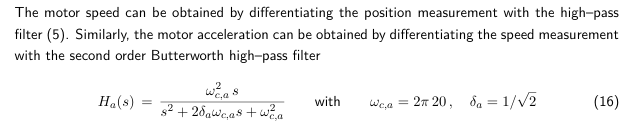


% Obtain motor acceleration using filter at (16)
sysHi = tf([rdp.wci^2 0], [1, 2*rdp.di*rdp.wci, rdp.wci^2]);
sysHi = c2d(sysHi, Ts, 'tustin');
[numHi, denHi] = tfdata(sysHi, 'v');

%%%%%%%%alk = filter(numHi, denHi, omega_l1/1000);
alk = filter(numHi, denHi, omega_l1);

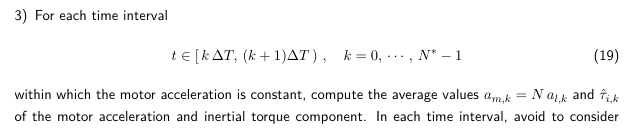

amk = alk*gbox.N;

% Plot amk confront with plot 4.b in Laboratory assignment
figure
plot(t,amk/1000);
title('Acceleration profile')
grid on
grid minor
xlabel('Time [s]');
ylabel('a_m [krpm/s]');
axis([0 8 -10 10])

% Create an empy vector for motor acceleration 

amv = zeros(45,1); 

% Compute the average value of acceleration am. Time = 45 s, 1 s for every
% acceleration - deceleration phase

duration1 = 45;
offset1 = 250;
T1 = round(size(amk,1)/duration1);

for x=1:1:45
   y1 = ((x-1))*T1+offset1;
   y2 = T1*x - offset1;
   amv(x) = mean(amk(y1:y2));
end

% Load friction value need to compute point (17) motor torque

friction_value = load('Lab_0_automatized\Generated_files\friction_value.mat');


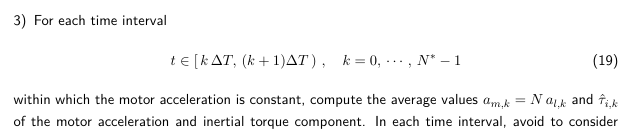

% Compute the frictional torque signal

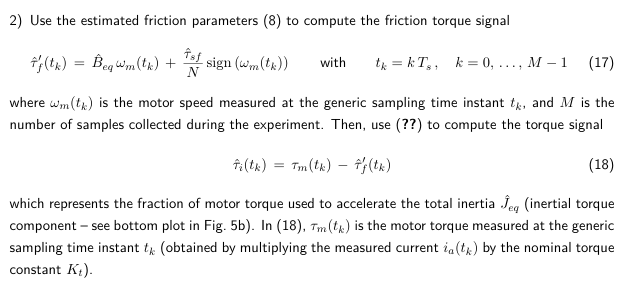

% Calculate taum (motor torque measured at time tk)

taum = mot.Kt*iaf1;
tauf = friction_value.Beq*omega_m/rads2rpm + friction_value.Tausf*sign(omega_m)/gbox.N;
taui = taum - tauf;
taui_mean = zeros(45,1);


% Perform the mean of taui

T2 = round(size(taui,1)/duration1);

for x=1:1:45
   y1 = ((x-1))*T2+offset1;
   y2 = T2*x - offset1;
   taui_mean(x) = mean(taui(y1:y2));
end

% plot taui
plot(t,taui);
title('Inertial Torque profile')
grid on
grid minor
xlabel('Time [s]');
ylabel('$\hat{\tau}_i$ [Nm]', 'Interpreter', 'latex')
axis([0 8 -5*10^-4 5*10^-4])

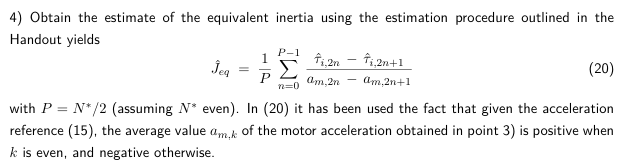

% Estimation of equivalent inertia

Je_l = zeros(10,1);
for i = 0:9
    Je_l(i+1) = abs(taui_mean(2*i+1) +taui_mean(2*i+2))/(amv(2*i+1)*rpm2rads - amv(2*i+2)*rpm2rads);
end

Je = mean(Je_l);

fprintf("Je =  %d Nm/(rad/s^2)\n'", Je);

% Save inertia data

save('Lab_0_automatized\Generated_files\Inertia_value.mat','Je_l','Je');

## Alternative approach

phi_a  = [amk*rpm2rads omega_m*rpm2rads (sign(omega_m)/gbox.N)];

Y_a = taum;

lsn_a = phi_a\Y_a;

fprintf('Total rotor inertia estimation Je = %d Nm/(rad/s^2)\n', lsn_a(1,1));
fprintf('Total friction viscous coefficient estimation Be = %d Nm/(rad/s^2)\n', lsn_a(2,1));
fprintf('Static friction estimation tausf = %d Nm/(rad/s^2)\n', lsn_a(3,1));